# MatNWB Optical Physiology Tutorial

## Introduction

In this tutorial, we will create fake data for a hypothetical optical physiology experiment with a freely moving animal. The types of data we will convert are:

- Acquired two-photon images

- Image segmentation (ROIs)

- Fluorescence and dF/F response

It is recommended to first work through the [Introduction to MatNWB tutorial](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/intro.html), which demonstrates installing MatNWB and creating an NWB file with subject information, animal position, and trials, as well as writing and reading NWB files in MATLAB.

## Set up the NWB file

An NWB file represents a single session of an experiment. Each file must have a session_description, identifier, and session start time. Create a new `NWBFile` object with those and additional metadata. For all MatNWB functions, we use the Matlab method of entering keyword argument pairs, where arguments are entered as name followed by value.

nwb = NwbFile( ...
    'session_description', 'mouse in open exploration',...
    'identifier', 'Mouse5_Day3', ...
    'session_start_time', datetime(2018, 4, 25, 2, 30, 3), ...
    'general_experimenter', 'LastName, FirstName', ... % optional
    'general_session_id', 'session_1234', ... % optional
    'general_institution', 'University of My Institution', ... % optional
    'general_related_publications', 'DOI:10.1016/j.neuron.2016.12.011'); % optional
nwb

## Optical Physiology

Optical physiology results are written in four steps:

- Create imaging plane

- Acquired two-photon images

- Image segmentation

- Fluorescence and dF/F responses

### Imaging Plane

First, you must create an [`ImagingPlane`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ImagingPlane.html) object, which will hold information about the area and method used to collect the optical imaging data. This requires creation of a [`Device`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Device.html) object for the microscope and an [`OpticalChannel`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/OpticalChannel.html) object. Then you can create an [`ImagingPlane`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ImagingPlane.html).

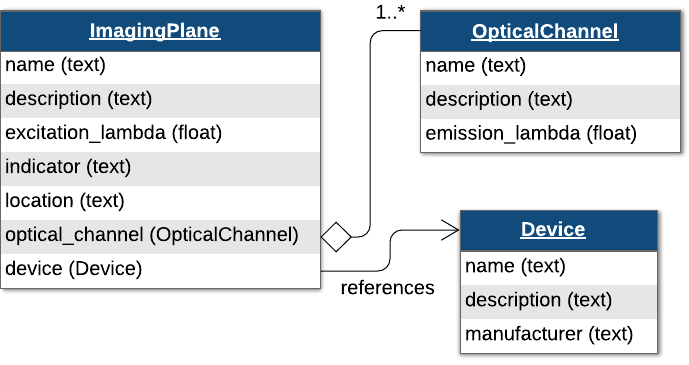

optical_channel = types.core.OpticalChannel( ...
    'description', 'description', ...
    'emission_lambda', 500.);

device = types.core.Device();
nwb.general_devices.set('Device', device);

imaging_plane_name = 'imaging_plane';
imaging_plane = types.core.ImagingPlane( ...
    'optical_channel', optical_channel, ...
    'description', 'a very interesting part of the brain', ...
    'device', types.untyped.SoftLink(device), ...
    'excitation_lambda', 600., ...
    'imaging_rate', 5., ...
    'indicator', 'GFP', ...
    'location', 'my favorite brain location');

nwb.general_optophysiology.set(imaging_plane_name, imaging_plane);

### Storing One-Photon Data

Now that we have our [`ImagingPlane`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ImagingPlane.html), we can create a [`OnePhotonSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/OnePhotonSeries.html) object to store raw one-photon imaging data. Here, we have two options. The first option is to supply the raw image data using the `data` argument. The second option is to provide a path to the image files. These two options have trade-offs, so it is worth considering how you want to store this data.

% using internal data. this data will be stored inside the NWB file
InternalOnePhoton = types.core.OnePhotonSeries( ...
    'data', ones(1000, 100, 100), ...
    'imaging_plane', imaging_plane, ...
    'starting_time_rate', 1.0, ...
    'data_unit', 'normalized amplitude' ...
);

% using external data. only the file paths will be stored inside the NWB file
ExternaLOnePhoton = types.core.OnePhotonSeries( ...
    dimension=[100, 100], ...
    external_file=["images.tiff"], ...
    'imaging_plane', imaging_plane, ...
    starting_frame=[0], ...
    format="external", ...
    starting_time=0.0, ...
    rate=1.0 ...
)

Since these data are acquired, we will add the [`OnePhotonSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/OnePhotonSeries.html) objects to the [`NWBFile`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/NWBFile.html) as acquired data.

nwb.acquisition.set('internal1p', InternalOnePhoton);
nwb.acquisition.set('external1p', ExternalOnePhoton);

### Storing Two-Photon Data

You can create a [`TwoPhotonSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/TwoPhotonSeries.html) the class representing two photon imaging data. [`TwoPhotonSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/TwoPhotonSeries.html), like [`SpatialSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/SpatialSeries.html), inherits from [`TimeSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/TimeSeries.html) and is similar in concept to the [`OnePhotonSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/OnePhotonSeries.html)`.`

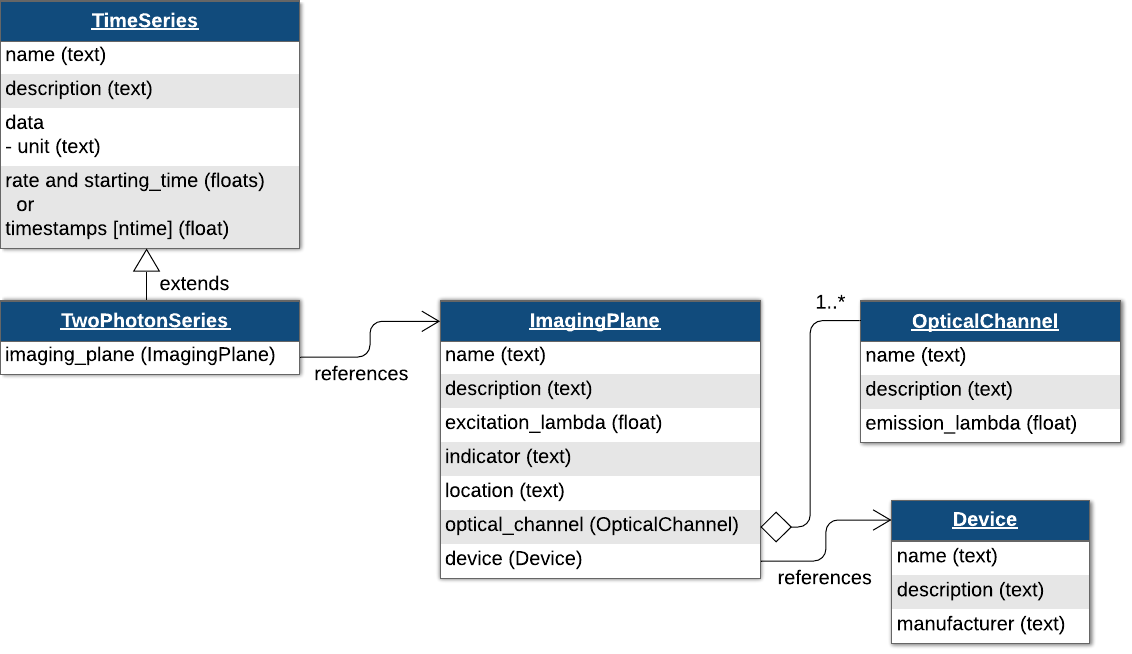

From here you have two options. The first option is to supply the image data using the `data` argument. The other option is the provide a path the images. These two options have trade-offs, so it is worth spending time considering how you want to store this data.

#### Adding the data directly to the NWBFile

image_series = types.core.TwoPhotonSeries( ...
    'imaging_plane', types.untyped.SoftLink(imaging_plane), ...
    'starting_time', 0.0, ...
    'starting_time_rate', 3.0, ...
    'data', ones(200, 100, 1000), ...
    'data_unit', 'lumens');

nwb.acquisition.set('TwoPhotonSeries', image_series);

#### Linking externally to the data

image_series = types.core.TwoPhotonSeries( ...
    'external_file', 'images.tiff', ...
    'imaging_plane', types.untyped.SoftLink(imaging_plane), ...
    'external_file_starting_frame', 0, ...
    'format', 'tiff', ...
    'starting_time_rate', 3.0, ...
    'starting_time', 0.0, ...
    'data', NaN(2, 2, 2), ...
    'data_unit', 'lumens');

nwb.acquisition.set('TwoPhotonSeries2', image_series);

### Plane Segmentation

Image segmentation stores the detected regions of interest in the [`TwoPhotonSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/TwoPhotonSeries.html) data. [`ImageSegmentation`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ImageSegmentation.html) allows you to have more than one segmentation by creating more [`PlaneSegmentation`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/PlaneSegmentation.html) objects.

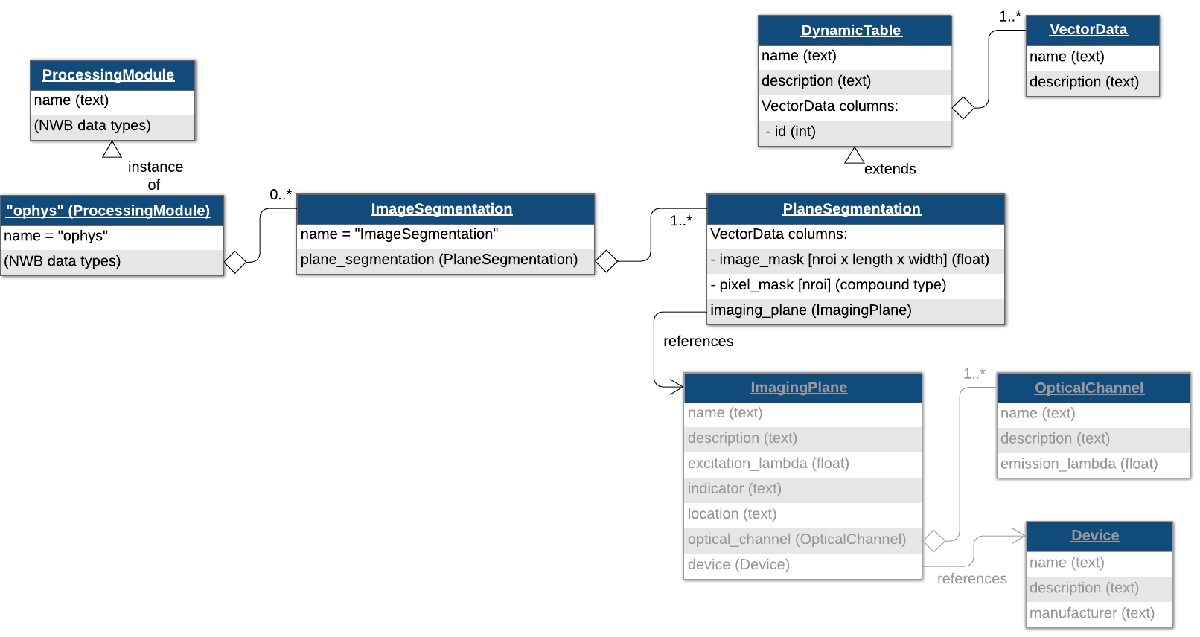

### Regions of interest (ROIs)

Add ROIs using an image mask. An image mask is an array that is the same size as a single frame of the [`TwoPhotonSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/TwoPhotonSeries.html), and indicates where a single region of interest is. This image mask may be boolean or continuous between 0 and 1.

% generate fake image_mask data
imaging_shape = [100, 100];
x = imaging_shape(1);
y = imaging_shape(2);

n_rois = 20;
image_mask = zeros(y, x, n_rois);
for i = 1:n_rois
    start = randi(90,2,1);
    image_mask(start(1):start(1)+10, start(2):start(2)+10, 1) = 1;
end

% add data to NWB structures
plane_segmentation = types.core.PlaneSegmentation( ...
    'colnames', {'image_mask'}, ...
    'description', 'output from segmenting my favorite imaging plane', ...
    'id', types.hdmf_common.ElementIdentifiers('data', int64(0:19)), ...
    'imaging_plane', types.untyped.SoftLink(imaging_plane), ...
    'image_mask', types.hdmf_common.VectorData('data', image_mask, 'description', 'image masks') ...
);

Now create an [`ImageSegmentation`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ImageSegmentation.html) object and put the `plane_segmentation` object inside of it, naming it [`PlaneSegmentation`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/PlaneSegmentation.html).

img_seg = types.core.ImageSegmentation();
img_seg.planesegmentation.set('PlaneSegmentation', plane_segmentation)

Now create a [`ProcessingModule`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ProcessingModule.html) called "ophys" and put our `img_seg` object in it, calling it "`ImageSegmentation"`, and add the [`ProcessingModule`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ProcessingModule.html) to `nwb.`

ophys_module = types.core.ProcessingModule( ...
    'description',  'contains optical physiology data')
ophys_module.nwbdatainterface.set('ImageSegmentation', img_seg);
nwb.processing.set('ophys', ophys_module);

### Storing fluorescence of ROIs over time

Now that ROIs are stored, you can store fluorescence dF/F data for these regions of interest. This type of data is stored using the [`RoiResponseSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/RoiResponseSeries.html) class. You will not need to instantiate this class directly to create objects of this type, but it is worth noting that this is the class you will work with after you read data back in.

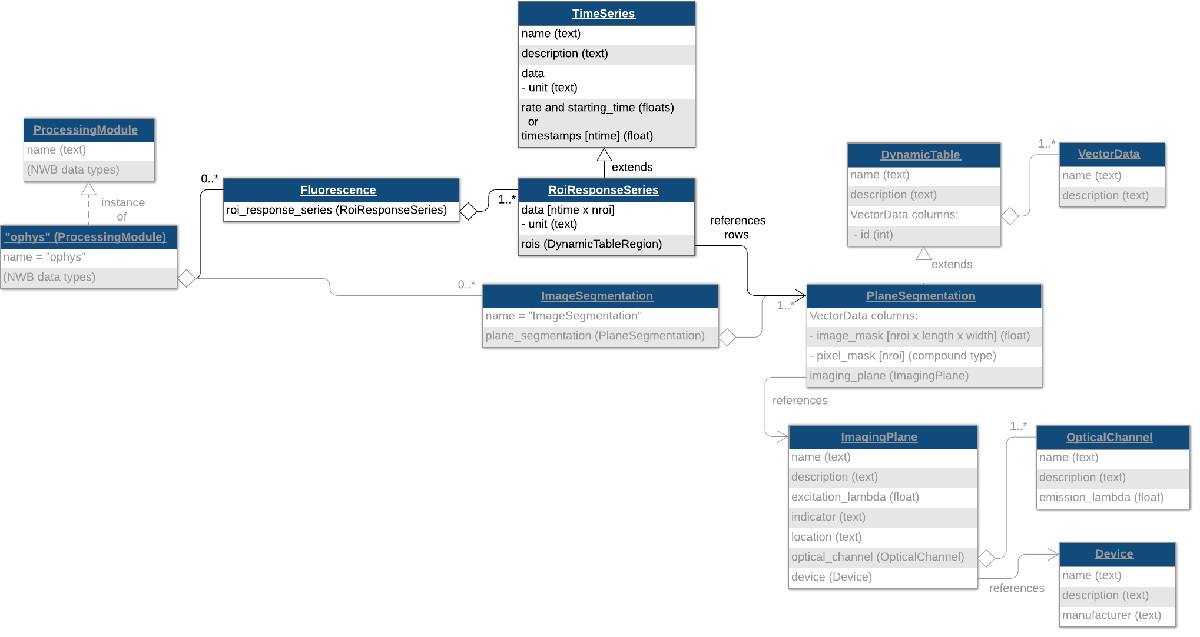

First, create a data interface to store this data in

roi_table_region = types.hdmf_common.DynamicTableRegion( ...
    'table', types.untyped.ObjectView(plane_segmentation), ...
    'description', 'all_rois', ...
    'data', (0:n_rois-1)');

roi_response_series = types.core.RoiResponseSeries( ...
    'rois', roi_table_region, ...
    'data', NaN(n_rois, 100), ...
    'data_unit', 'lumens', ...
    'starting_time_rate', 3.0, ...
    'starting_time', 0.0);

fluorescence = types.core.Fluorescence();
fluorescence.roiresponseseries.set('RoiResponseSeries', roi_response_series);

ophys_module.nwbdatainterface.set('Fluorescence', fluorescence);

Finally, the ophys [`ProcessingModule`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ProcessingModule.html) is added to the `NwbFile`.

nwb.processing.set('ophys', ophys_module);

Write the NWB file

nwbExport(nwb, 'ophys_tutorial.nwb');

## Reading the NWB file

read_nwb = nwbRead('ophys_tutorial.nwb', 'ignorecache');

Data arrays are read passively from the file. Calling `TimeSeries.data` does not read the data values, but presents an HDF5 object that can be indexed to read data. 

read_nwb.processing.get('ophys').nwbdatainterface.get('Fluorescence')...
    .roiresponseseries.get('RoiResponseSeries').data

This allows you to conveniently work with datasets that are too large to fit in RAM all at once. Access the data in the matrix using the `load` method. 

`load` with no input arguments reads the entire dataset:


read_nwb.processing.get('ophys').nwbdatainterface.get('Fluorescence'). ...
    roiresponseseries.get('RoiResponseSeries').data.load

If all you need is a section of the data, you can read only that section by indexing the `DataStub` object like a normal array in MATLAB. This will just read the selected region from disk into RAM. This technique is particularly useful if you are dealing with a large dataset that is too big to fit entirely into your available RAM.

read_nwb.processing.get('ophys'). ...
    nwbdatainterface.get('Fluorescence'). ...
    roiresponseseries.get('RoiResponseSeries'). ...
    data(1:5, 1:10)
% read back the image masks
read_nwb.processing.get('ophys'). ...
    nwbdatainterface.get('ImageSegmentation'). ...
    planesegmentation.get('PlaneSegmentation'). ...
    image_mask.data.load

# Learn more!

### See the [API documentation](https://neurodatawithoutborders.github.io/matnwb/doc/index.html) to learn what data types are available.

## Other MatNWB tutorials

- [Extracellular electrophysiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/ecephys.html)

- [Intracellular electrophysiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/icephys.html)

## Python tutorials

See our tutorials for more details about your data type:

- [Extracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ecephys.html#sphx-glr-tutorials-domain-ecephys-py)

- [Calcium imaging](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ophys.html#sphx-glr-tutorials-domain-ophys-py)

- [Intracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/icephys.html#sphx-glr-tutorials-domain-icephys-py)

**Check out other tutorials that teach advanced NWB topics:**

- [Iterative data write](https://pynwb.readthedocs.io/en/stable/tutorials/general/iterative_write.html#sphx-glr-tutorials-general-iterative-write-py)

- [Extensions](https://pynwb.readthedocs.io/en/stable/tutorials/general/extensions.html#sphx-glr-tutorials-general-extensions-py)

- [Advanced HDF5 I/O](https://pynwb.readthedocs.io/en/stable/tutorials/general/advanced_hdf5_io.html#sphx-glr-tutorials-general-advanced-hdf5-io-py)